## **Simulation for Active Structures -- A Living Textbook**

**by Yi Zhu (PhD)**

clear all; 
close all; 
clc;

***Please add "00_SourceCode_Elements" and "00_SourceCode_Solver" into path before running the code***

**Section 05 - Example 01 - Truss Loading**

Here, we hope to introduce the basic structures of the code packages through using a simple case study - loading of a structurally determinante 2D trusses as shown in the figure below. This truss has four 1-meter span and is 1 meter tall. The cross section is made with a 1cm by 1cm plastic like material with a Young's modulus of 2GPa. We will assume that a 1000 N force is applied to the center node of the truss and we want to neglect all the potential buckling for this case. Let's try to find the internal force.

 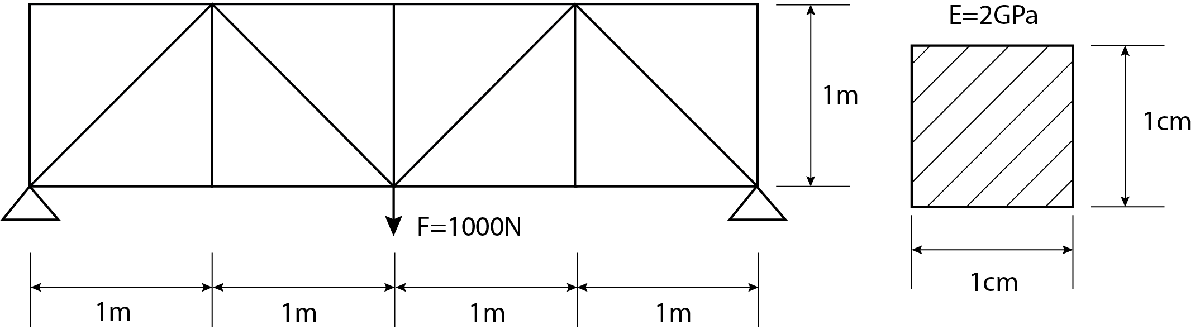

First, we try to innitialize the model and define basic variables we will need to use for the modeling process. Here, we will need the height of the truss $H=1m$; the length of each span $L=1m$; The area of the truss elements $\textrm{barA}=0\ldotp 0001m^{2\;} ;$ and finally, the Young's modulus of the bar $\textrm{barE}=2\times {10}^{9\;} \textrm{Pa}$. 

If you are from the US, I am so sorry for you, but please ditch your beloved emperical unit and embrace international unit. If everything is in basic international unit (m, N, kg, sec, etc.) , no unit conversion is ever needed in coding. This is also true for many FEM software you may need to use in the future. ;) 

%% Initialize the truss
% Define the nodes
H=1; % Height of the truss
L=1; % Length of each span
barA=0.0001; % cross section area (m^2)
barE=2*10^9; % Youngs' modulus (Pa)

Anyway, get back to the code. 

We will next create the node object and bar object based on the class "Elements_Nodes" and "CD_Elements_Bars". The class is like a template of an object while the object is what we can directly use in coding. Basically, we can think of "node" as a 3D printed tool we can directly use in our hand, but the "Elements_Nodes" is a 3D model, or a template, we can print multiple times.

% Define the node object
node=Elements_Nodes;
% Create the bar object
bar=CD_Elements_Bars;

After setting up the bar and the node object, we can create the assembly for the truss, which is also an object. This assembly class is created to help with the ploting and code organization. We will set the "node" variable in the "assembly" to be the "node" object we just created and set the "bar" variable in the "assembly" to be the "bar" object we just created. The overall assembly class organization is as the following. The variables of the assembly class include the "node" and the "bar" class. The "bar" class has a function that can output global force vector and global stiffness matrix when inputting the node information and the nodal displacement "U". The function of the assembly class include "Initialize_Assembly" and "Solve_FK". The function "Solve_FK" is the one that is been used to communicate with nonlinear solver. Because we only have one type of elements in this assembly, this function uses the force and stiffness results computed withe the bar class and directly return it. When we have multiple element types (which we will see in the next section), we will need to sum the forces and stiffness. 

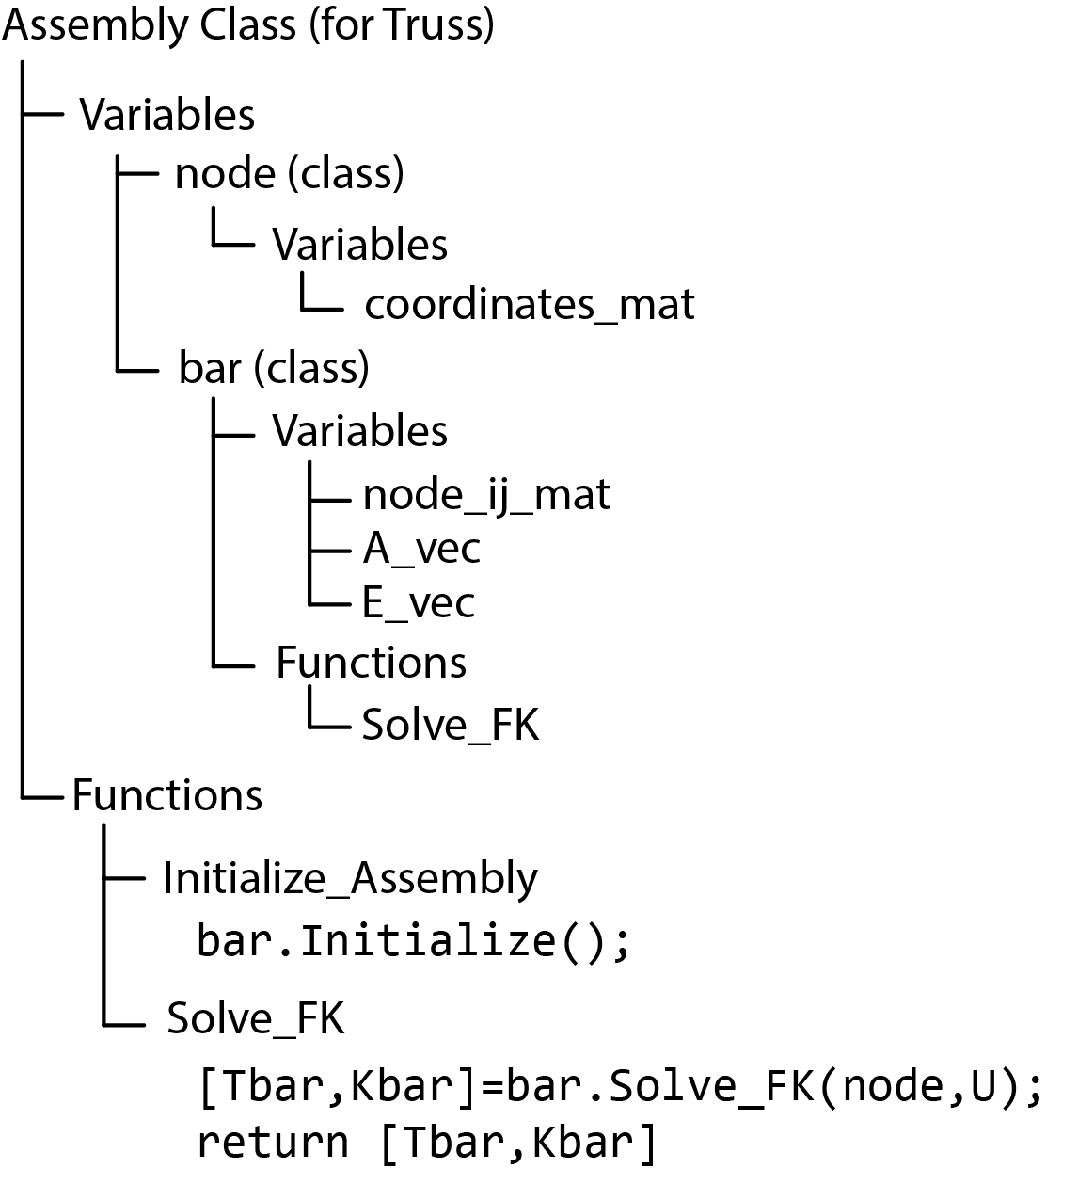

% Create tje truss Assembly
assembly=Assembly_Truss;
% This assembly has a node object and a bar object
assembly.node=node;
assembly.bar=bar;

After seting up the objects, we will define the nodal coordinates. Here, a total of 10 node is needed and they are stored in the matrix "coordinates_mat" in the node object. 

%% Define the nodal coordinates
% Here we need to set up the nodal coordinates of our truss
node.coordinates_mat=[0*L 0 0; 
                      1*L 0 0;
                      2*L 0 0; 
                      3*L 0 0; 
                      4*L 0 0; % Node 5
                      0*L 0 H; 
                      1*L 0 H;
                      2*L 0 H; 
                      3*L 0 H; 
                      4*L 0 H; % Node 10
                      ];

Here the nodes are located in the XZ plane. This is why the second column (Y-axis) is all zero for the matrix. Now, to check if we entered the correct nodal coordinates or not, we can use the following plotting function. Again, "plots" is an object of the class "Plot_Truss". Here, we set the assembly variable in the object to be the "assembly" object we just created. 

% Set up the plotting function for inspection
plots=Plot_Truss();
plots.assembly=assembly;
% We will plot for the truss assembly

Before plotting, we set a couple variable for the plotting function. This include the range we want to plot and the angles we hope to look into the object. Here, 0 for the viewAngle1 and viewAngle2 will give us the XZ plane. We next plot the place of this node. 

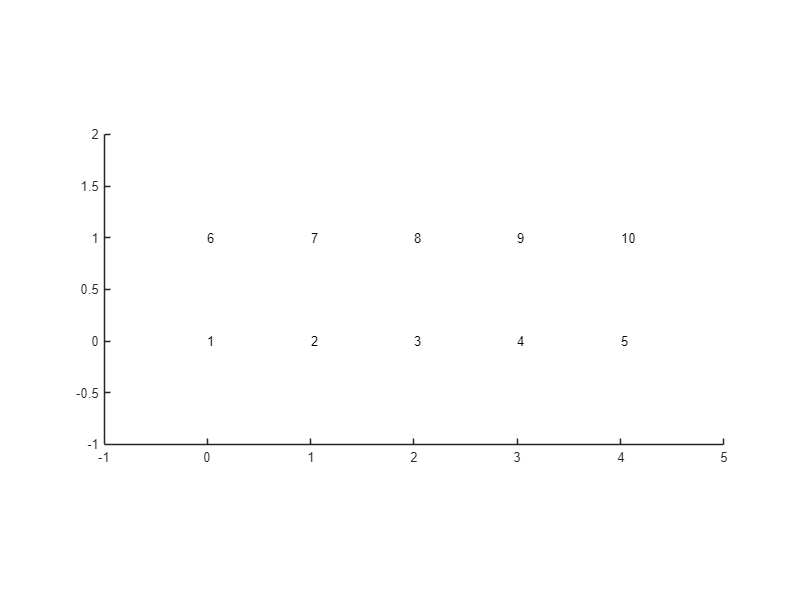

plots.displayRange=[-1;5;-1;1;-1;2]; 
plots.viewAngle1=0;
plots.viewAngle2=0;
% Change the viewing angle

% Plot the nodal coordinates for inspection
plots.Plot_Shape_Node_Number()

Looking good!

We have the 10 nodes located exactly at where we want them to be. 

Now that have the nodes defined, we can further define the bar (truss) elements. Here we need to add rows to the matrix "node_ij_mat" in the bar object. Each row of the matrix gives the two node of one bar. For instance, the first row of the "node_ij_mat" matrix is used to define the first bar element, and this element connects node 1 and node 2. 

% Define how bars are connected
% First we do the horizontal truss (bars)
bar.node_ij_mat=[1,2;
                 2,3;
                 3,4;
                 4,5;
                 6,7;
                 7,8;
                 8,9;
                 9,10;]; % 8 bars

% Next we do the vertical truss (bars)
bar.node_ij_mat=[bar.node_ij_mat;                    
                    1,6;
                    2,7;
                    3,8;
                    4,9;
                    5,10;]; % 5 bars

% Finally, we do the diagonal truss (bars)
bar.node_ij_mat=[bar.node_ij_mat;                    
                    1,7;
                    3,7;
                    3,9;
                    5,9;];  % 4 bars

After setting how how bars are connected, we will continue to define the properties of the bar (truss) element - the area of each truss and the Young's modulus of each truss. This is done with the following code.

% Define the area of the bars
% We have a total of 4+5+8=17 bars
bar.A_vec=barA*ones(17,1);
bar.E_vec=barE*ones(17,1);

Now that we have defined all the structure, we can initialize the full assembly and plot the bar (truss) we just defined. In addition to plotting the shape of the truss, we also have the bar number of each truss shown in the right figure.

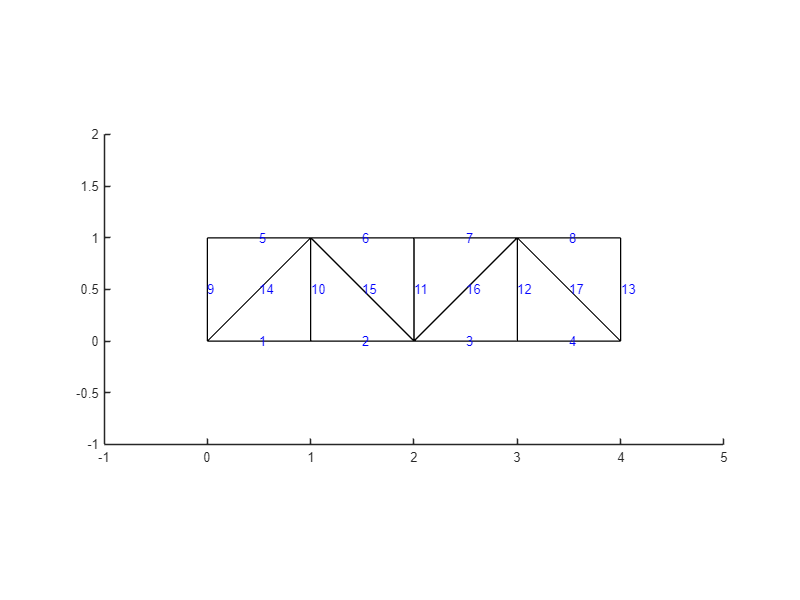

% Initialize the entire assembly 
assembly.Initialize_Assembly();
% Set up the 
plots.Plot_Shape_Bar_Number()

 It looks like everything is working perfectly!

With the structure setted up, we can now define the loading situation. We will set up a Newton-Raphson solver to solve for the responses in the structure. "nr" is the object created based on the solver class "Solver_NR_Loading". We set the assembly to be our truss and then set up the support. Here, each row in the "supp" matrix represents one support. The first column is used to represent the node number while the remaining three columns are used to represent if XYZ deformation is restricted or not (1 means support provided, 0 means free to move). Because this is a 2D problem, the Y-axis deformation is all restricted. 

%% Set up the loading solver
nr=Solver_NR_Loading;
nr.assembly=assembly;
nr.supp=[1,1,1,1;
         2,0,1,0;
         3,0,1,0;
         4,0,1,0;
         5,1,1,1;
         6,0,1,0;
         7,0,1,0;
         8,0,1,0;
         9,0,1,0;
         10,0,1,0;];

Next, we will set up the load at the mid spaen. Here, we will apply a load of -100 N at the 3rd node in the Z-direction. This matches what we draw in the problem statement

% Set up the load
nr.load=[3,0,0,-100];

We will load the structure in 10-steps creating a total of 1000N of force. Each step, we allow a maximum of 30 iterations to find the equilibrium using the Newton's method.

% Set up the total loading step
nr.increStep=10;
% Set up the maximum iteration
nr.iterMax=30;

Now that everything is creatd, we can ask the program to find the deformation history Uhis for us. This is done by asking the solver object "nr" to perform the "Solve()" function. 

% Solve for the deformation history
Uhis=nr.Solve();

Loading Analysis StartIcrement = 1
    Iteration = 1, R = 4.299451e-03
    Iteration = 2, R = 9.490514e-06
Icrement = 2
    Iteration = 1, R = 4.307368e-03
    Iteration = 2, R = 2.046313e-05
    Iteration = 3, R = 6.365786e-08
Icrement = 3
    Iteration = 1, R = 4.346623e-03
    Iteration = 2, R = 2.593952e-06
Icrement = 4
    Iteration = 1, R = 4.365955e-03
    Iteration = 2, R = 2.058678e-06
Icrement = 5
    Iteration = 1, R = 4.392005e-03
    Iteration = 2, R = 7.549434e-06
Icrement = 6
    Iteration = 1, R = 4.421869e-03
    Iteration = 2, R = 1.922660e-05
    Iteration = 3, R = 2.573353e-07
Icrement = 7
    Iteration = 1, R = 4.455445e-03
    Iteration = 2, R = 3.194151e-05
    Iteration = 3, R = 4.531499e-07
Icrement = 8
    Iteration = 1, R = 4.473037e-03
    Iteration = 2, R = 2.835555e-05
    Iteration = 3, R = 2.396416e-07
Icrement = 9
    Iteration = 1, R = 4.463053e-03
    Iteration = 2, R = 1.042600e-05
    Iteration = 3, R = 1.045075e-07
Icrement = 10
    Iteration = 1, 

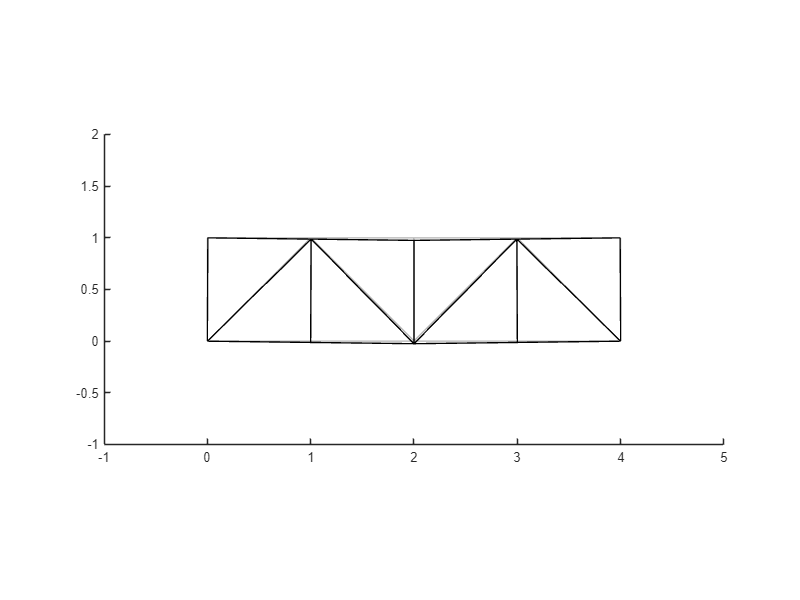

% Plot the deformed shape
plots.Plot_Deformed_Shape(squeeze(Uhis(end,:,:)));

After finding the deformation, we can further ask the software program to plot the deformation and the internal forces. To do that, we first find the internal forces of the bar at the final deformation. This can be done using the following code. The internal force is solved as:


$$F_I =\epsilon \times E\times A$$


for each bar (truss) element. In the following code, " .* " is element wise multiplication. We will end up having a 17 by 1 vector for the "internal_force". To make the plotting easier to read, we can set small values to be zero. 

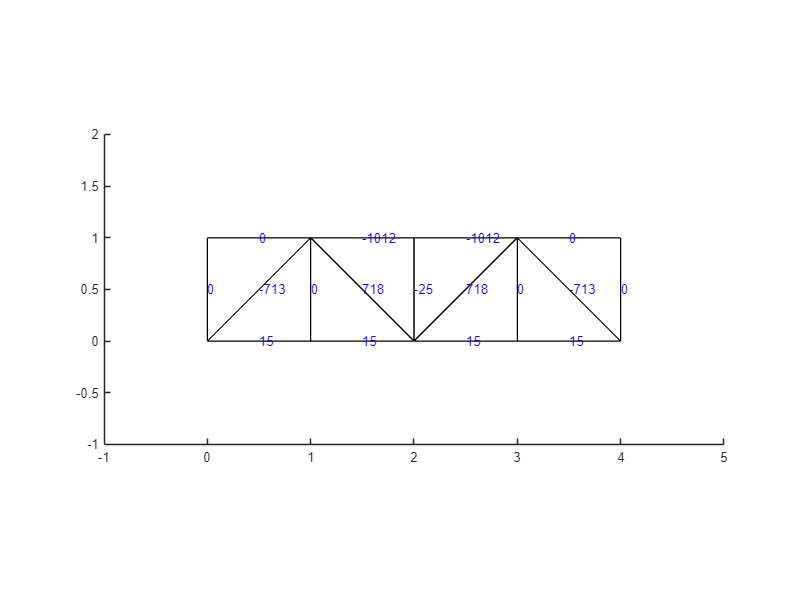

truss_strain=bar.Solve_Strain(node,squeeze(Uhis(end,:,:)));
internal_force=(truss_strain).*(bar.E_vec).*(bar.A_vec);
plots.Plot_Bar_Force(internal_force);

Now, to practice, please consider working out the following problems. 

**Problem 01 **

Solve for the analytical solution and compare with the result shown in the software. How close are they? Please note that the analytical solution is based on linear analysis and the code here is performing nonlinear analysis with consideration of large deformation (no buckling).

**Problem 02 **

Try to change the code for simulating a truss structure with 8 span (Adding two span to the left and two span to the rigth of the existing structure). Also change the truss organization.